# FFUAV Senior Design - James Objective Funtion

## Housekeeping

clc; clear; close all;

## Load Data

load("Battery_chem.mat");
load("All_motor_Prop_combos.mat");
load("all_batteries.mat");
i = 9;

## Inputs

% Propulsion System
Num_p_systems = 8; % Number of propulsion Systems
manufacture_offset = 1.075;
coaxial_system = 0;

% Battery Type and Sizing
Bat_Capacity = 40 % amp - Hours

Bat_Capacity = 40

number_of_cells = 12; 
Battery_Type = "Li-Hv"; % determines battery chemistery
Bat_Usage = 0.80;    % max battery allowed to be used

% Aircraft weight estimation - Grams
airframe = 7500;
Propulsion = 3600;
Autopilot_electronics = 500;
Payload = 25 * 453.592 % lbs --> grams

Payload = 1.1340e+04

misc = 500;

% Minumum Thrust to weight ratio
TW = 2.0;

if(coaxial_system)
    thrust_multiplier = 0.8;
else
    Thrust_multiplier = 1;
end

## Quadratic Fit of Motor thrust to power curves

Thrust_newtons = nonzeros(rmmissing(allMPCs(i).Thrust_N(:,2)));
Thrust_grams = Thrust_newtons * 101.971621297793; % convert to grams
Power_Watts = nonzeros(rmmissing((allMPCs(i).Power_W(:,2))));
total_thrust_newtons = Thrust_multiplier * Thrust_newtons * Num_p_systems;
total_thrust_grams = total_thrust_newtons * 101.971621297793; %convert to grams
total_power_watts = Num_p_systems * Power_Watts * manufacture_offset;
%plotting
quad_coefs = polyfit(Thrust_grams,Power_Watts,2)

quad_coefs =     0.0000    0.0714  -35.7533


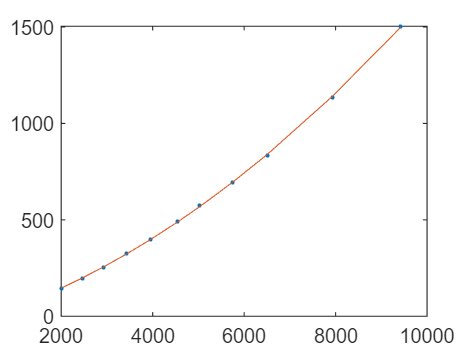

power_fit = polyval(quad_coefs,Thrust_grams);
plot(Thrust_grams,Power_Watts,'.')
hold on
plot(Thrust_grams,power_fit)

## output

low_battery_voltage = 